# Handling Class Imbalance

This reading accompanies the **Handling Class Imbalance** screencast.

## Preparation

Let's load the January taxi data and compare the number of taxi trips with tolls to the number of trips without tolls.

### Import the Data

taxiData = importTaxiDataWithoutCleaning("yellow_tripdata_2015-01.csv");

### View Class Imbalance

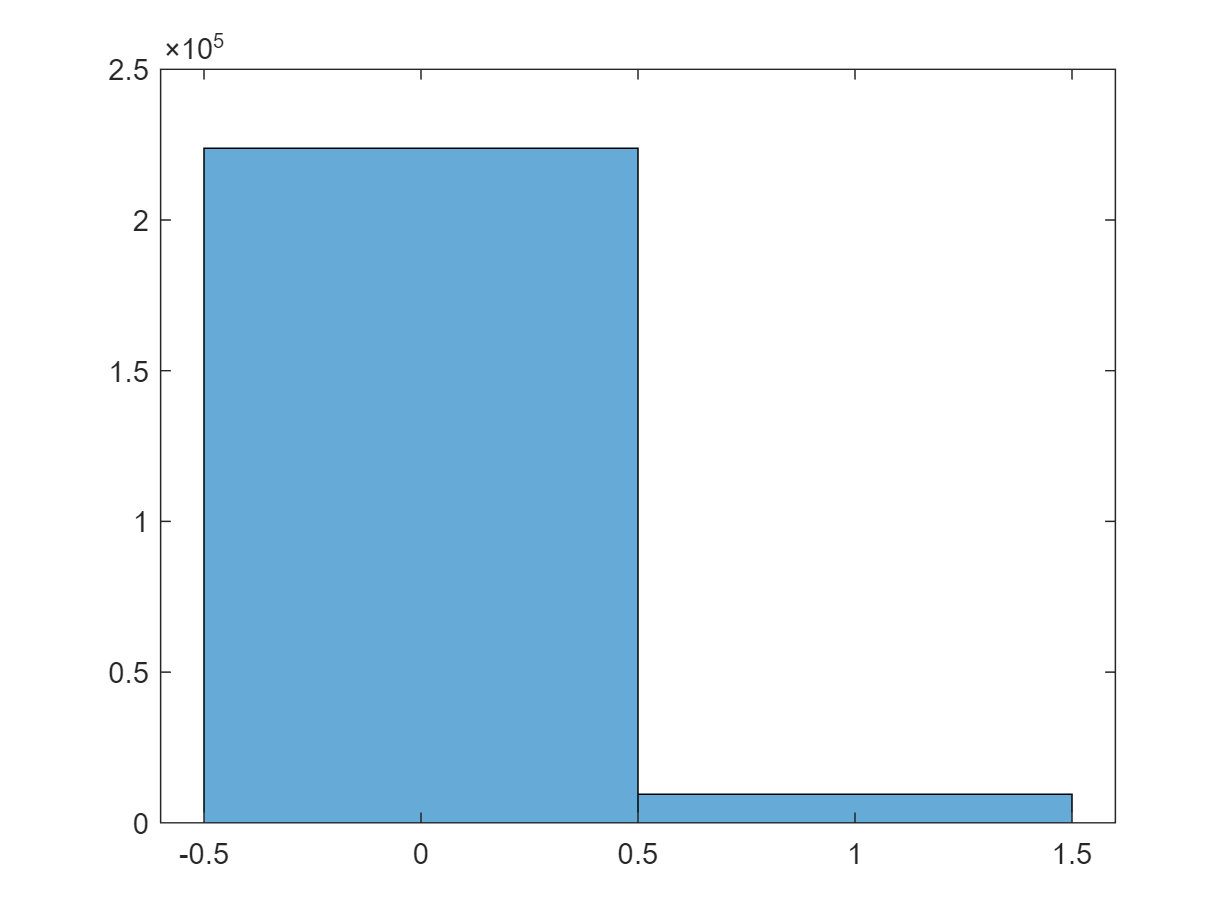

taxiTrips = basicPreprocessing(taxiData);
taxiTrips = addWasTollPaid(taxiTrips);
histogram(taxiTrips.WasTollPaid)

## Preprocessing

### Partition into Training and Testing Sets

First, divide the data into training and test sets.

taxiPartitions = cvpartition(height(taxiData),"HoldOut",0.2);
taxiTest = taxiData(taxiPartitions.test,:);
taxiTrain = taxiData(taxiPartitions.training,:); 

### Clean the Training Data and Add Features

Next, clean the training data and add the `wasTollPaid` feature.  To make the confusion charts easier to read, convert `wasTollPaid` to a categorial variable.  The chart will now have "Toll" and "No Toll" as labels instead of "True" and "False".

taxiTrain = basicPreprocessing(taxiTrain);
taxiTrain = addWasTollPaid(taxiTrain);

taxiTrain.WasTollPaid = categorical(taxiTrain.WasTollPaid);
taxiTrain.WasTollPaid = renamecats(taxiTrain.WasTollPaid,"false","No Toll");
taxiTrain.WasTollPaid = renamecats(taxiTrain.WasTollPaid,"true","Toll");

## Undersample the Majority Class

You're now ready to undersample the majority class, the trips without tolls. 

### Split Training Data by Response Class

taxiTrainNoToll = taxiTrain(taxiTrain.WasTollPaid == "No Toll",:);
taxiTrainToll = taxiTrain(taxiTrain.WasTollPaid == "Toll",:);

### Undersample the Majority Class Data

numberToSample = 10000;
taxiTrainUnderSampled = datasample(taxiTrainNoToll, numberToSample, "Replace", false);

### Combine Undersampled Majority Class Data with Minority Class Data 

taxiTrainSampled = [taxiTrainToll; taxiTrainUnderSampled];

### Visualizations

Check the new data set's distribution with a histogram.

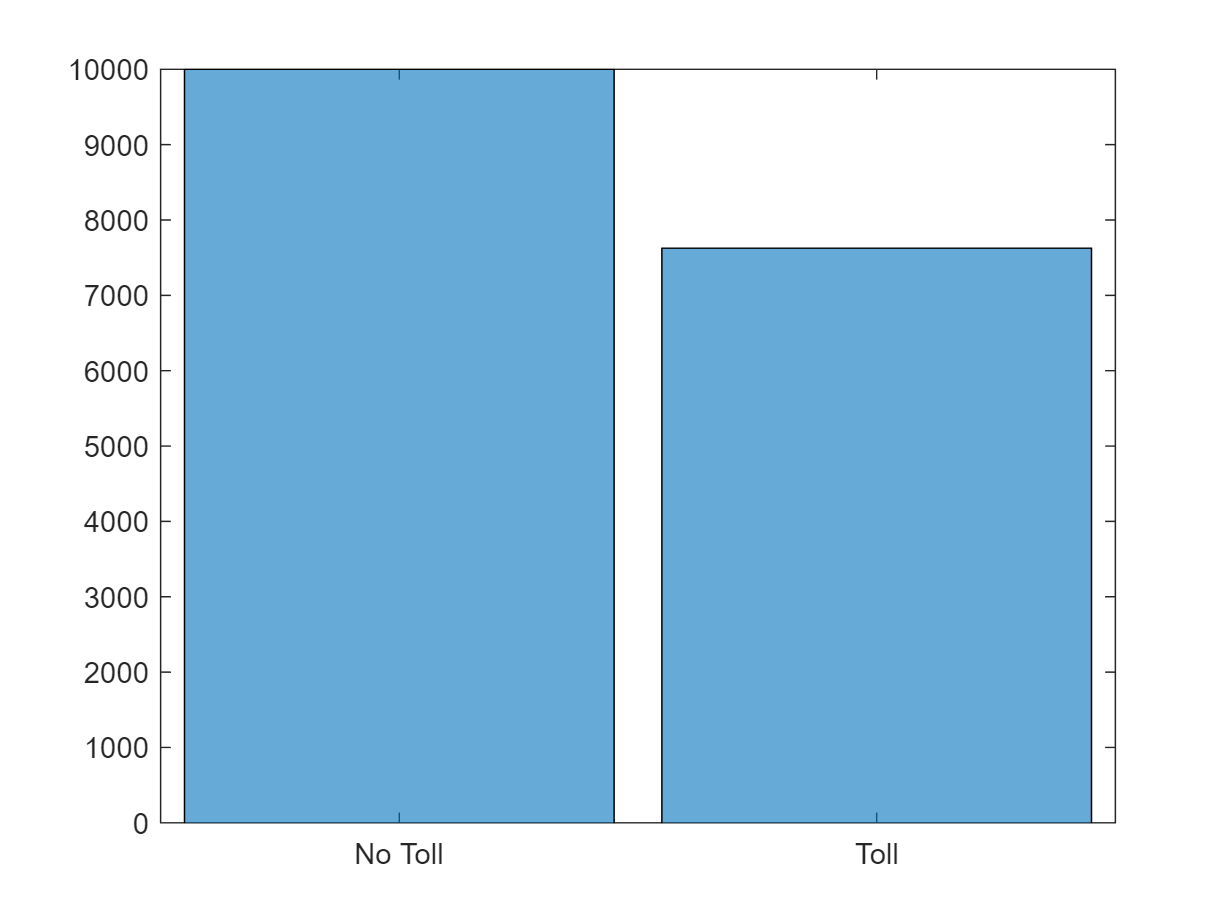

histogram(taxiTrainSampled.WasTollPaid)

The training data set now has roughly the same number of observations in each class.

## Training Models

With your new, balanced data set, it's time to train some models in the Classification Learner App.  The video showed Medium KNN and Fine Gaussian SVM models trained with 5-fold cross validation.  Feel free to try other models.  When you're happy with the results, export your models to MATLAB and use the steps below to verify their performance on the test data.

## Test Results

### Clean and Preprocess the Test Data

Before you can run the model on the test data. you'll need to clean the it and add the `wasTollPaid` feature.

### Used the Trained Models to Make Predictions

Now you can use your exported model's `predictFcn` function to predict which of the trips in the test data set will have a toll.

### Check the Predictions with a Confusion Chart

You can create confusion charts like those shown in the app using the `confusionchart` function.  The commented line of code shows how to add the True Positive Rate and False Negative Rate chart.

% confusionchart(actualValues,predictedValues,"RowSummary","row-normalized","Title","My Awesome Model");
